# MATLAB for Business Analytics: Forecasting, Optimization, and AI Agents

You will not need to write algorithms from scratch today.

Every technique here is a single MATLAB function or app - your job is to interpret what it tells you about the business, the same way you would read output from Excel, Power BI, or SPSS.

We follow one fictional retailer, **Brighten Up Mart**, through three connected decisions that any retail, logistics, or supply-chain manager faces every month.

- **Part 1 - Machine Learning for Forecasting:** how much will customers buy next quarter?

- **Part 2 - Transportation Optimization:** given that demand, what is the cheapest way to ship inventory to stores?

- **Part 3 - AI Agentics for Data Analytics and Dashboard Intelligence:** how do we turn all of this into a dashboard - and an assistant - that busy executives can actually use

## The Business Scenario

Brighten Up Mart is a Thai retail chain with three regional distribution centers and five stores.

Every month, the management team has to answer three questions: *How much will we sell?*, *How do we distribute stock at the lowest cost?*, and *How do we get answers fast, without waiting for an analyst?*

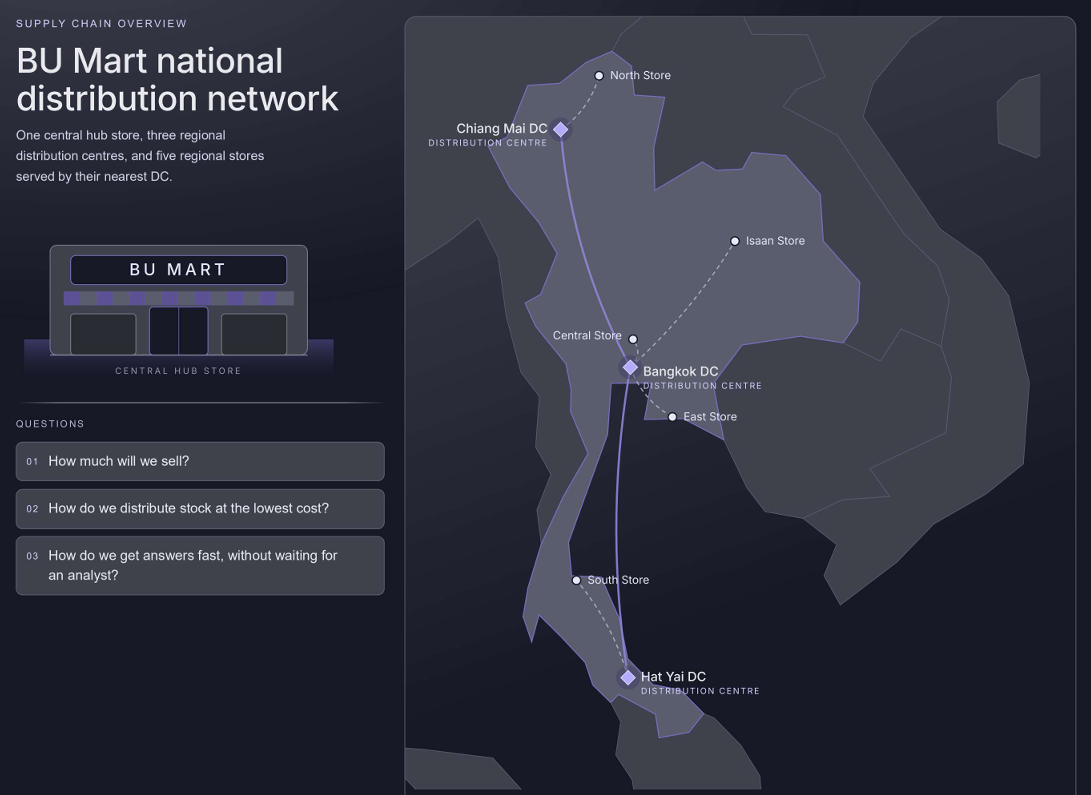

We start by loading four years of monthly sales history, together with the marketing budget spent each month - a common early-warning signal for demand.

### Import Data using Live Task

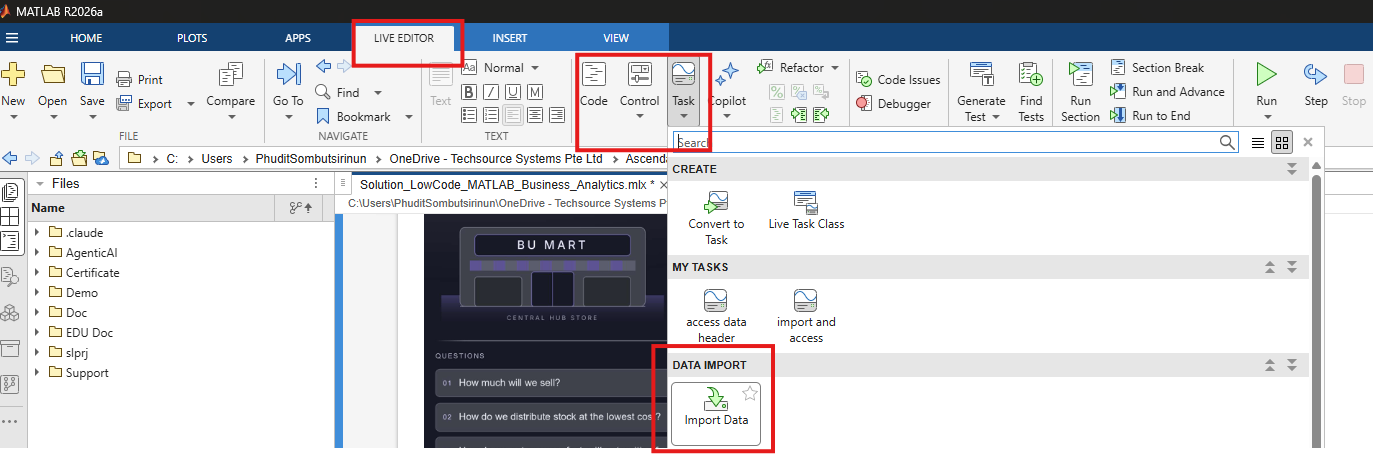

Want summary of the data?

## A First Look at the Data

Before modeling anything, always plot the raw series.

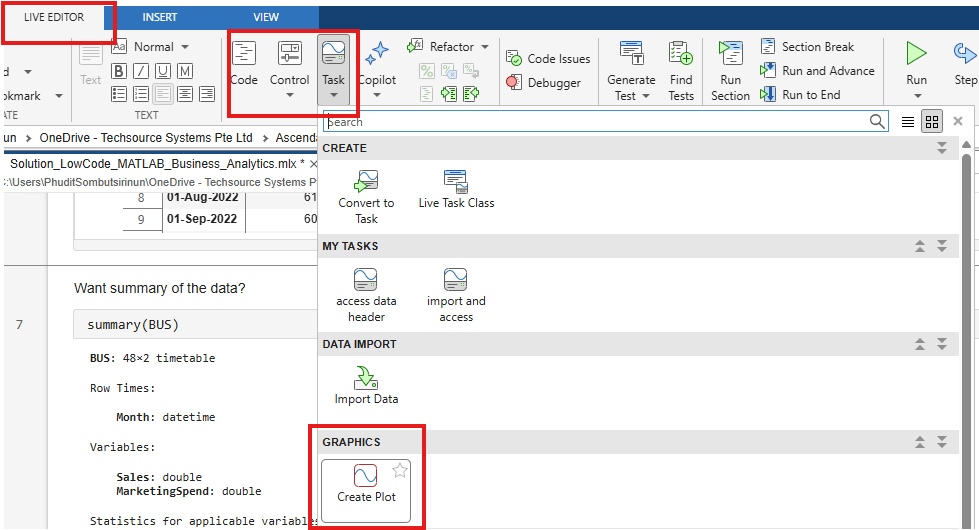

### Try to find some correlation between data

Sales against `MarketingSpend`: does spend actually move sales, that is, is it worth using as a predictor? 

### Plot unit sales in time

Sales against `Month`: is there a trend, and does the same shape repeat every 12 months?

## Part 1: Machine Learning for Forecasting

### Machine Learning Workflow

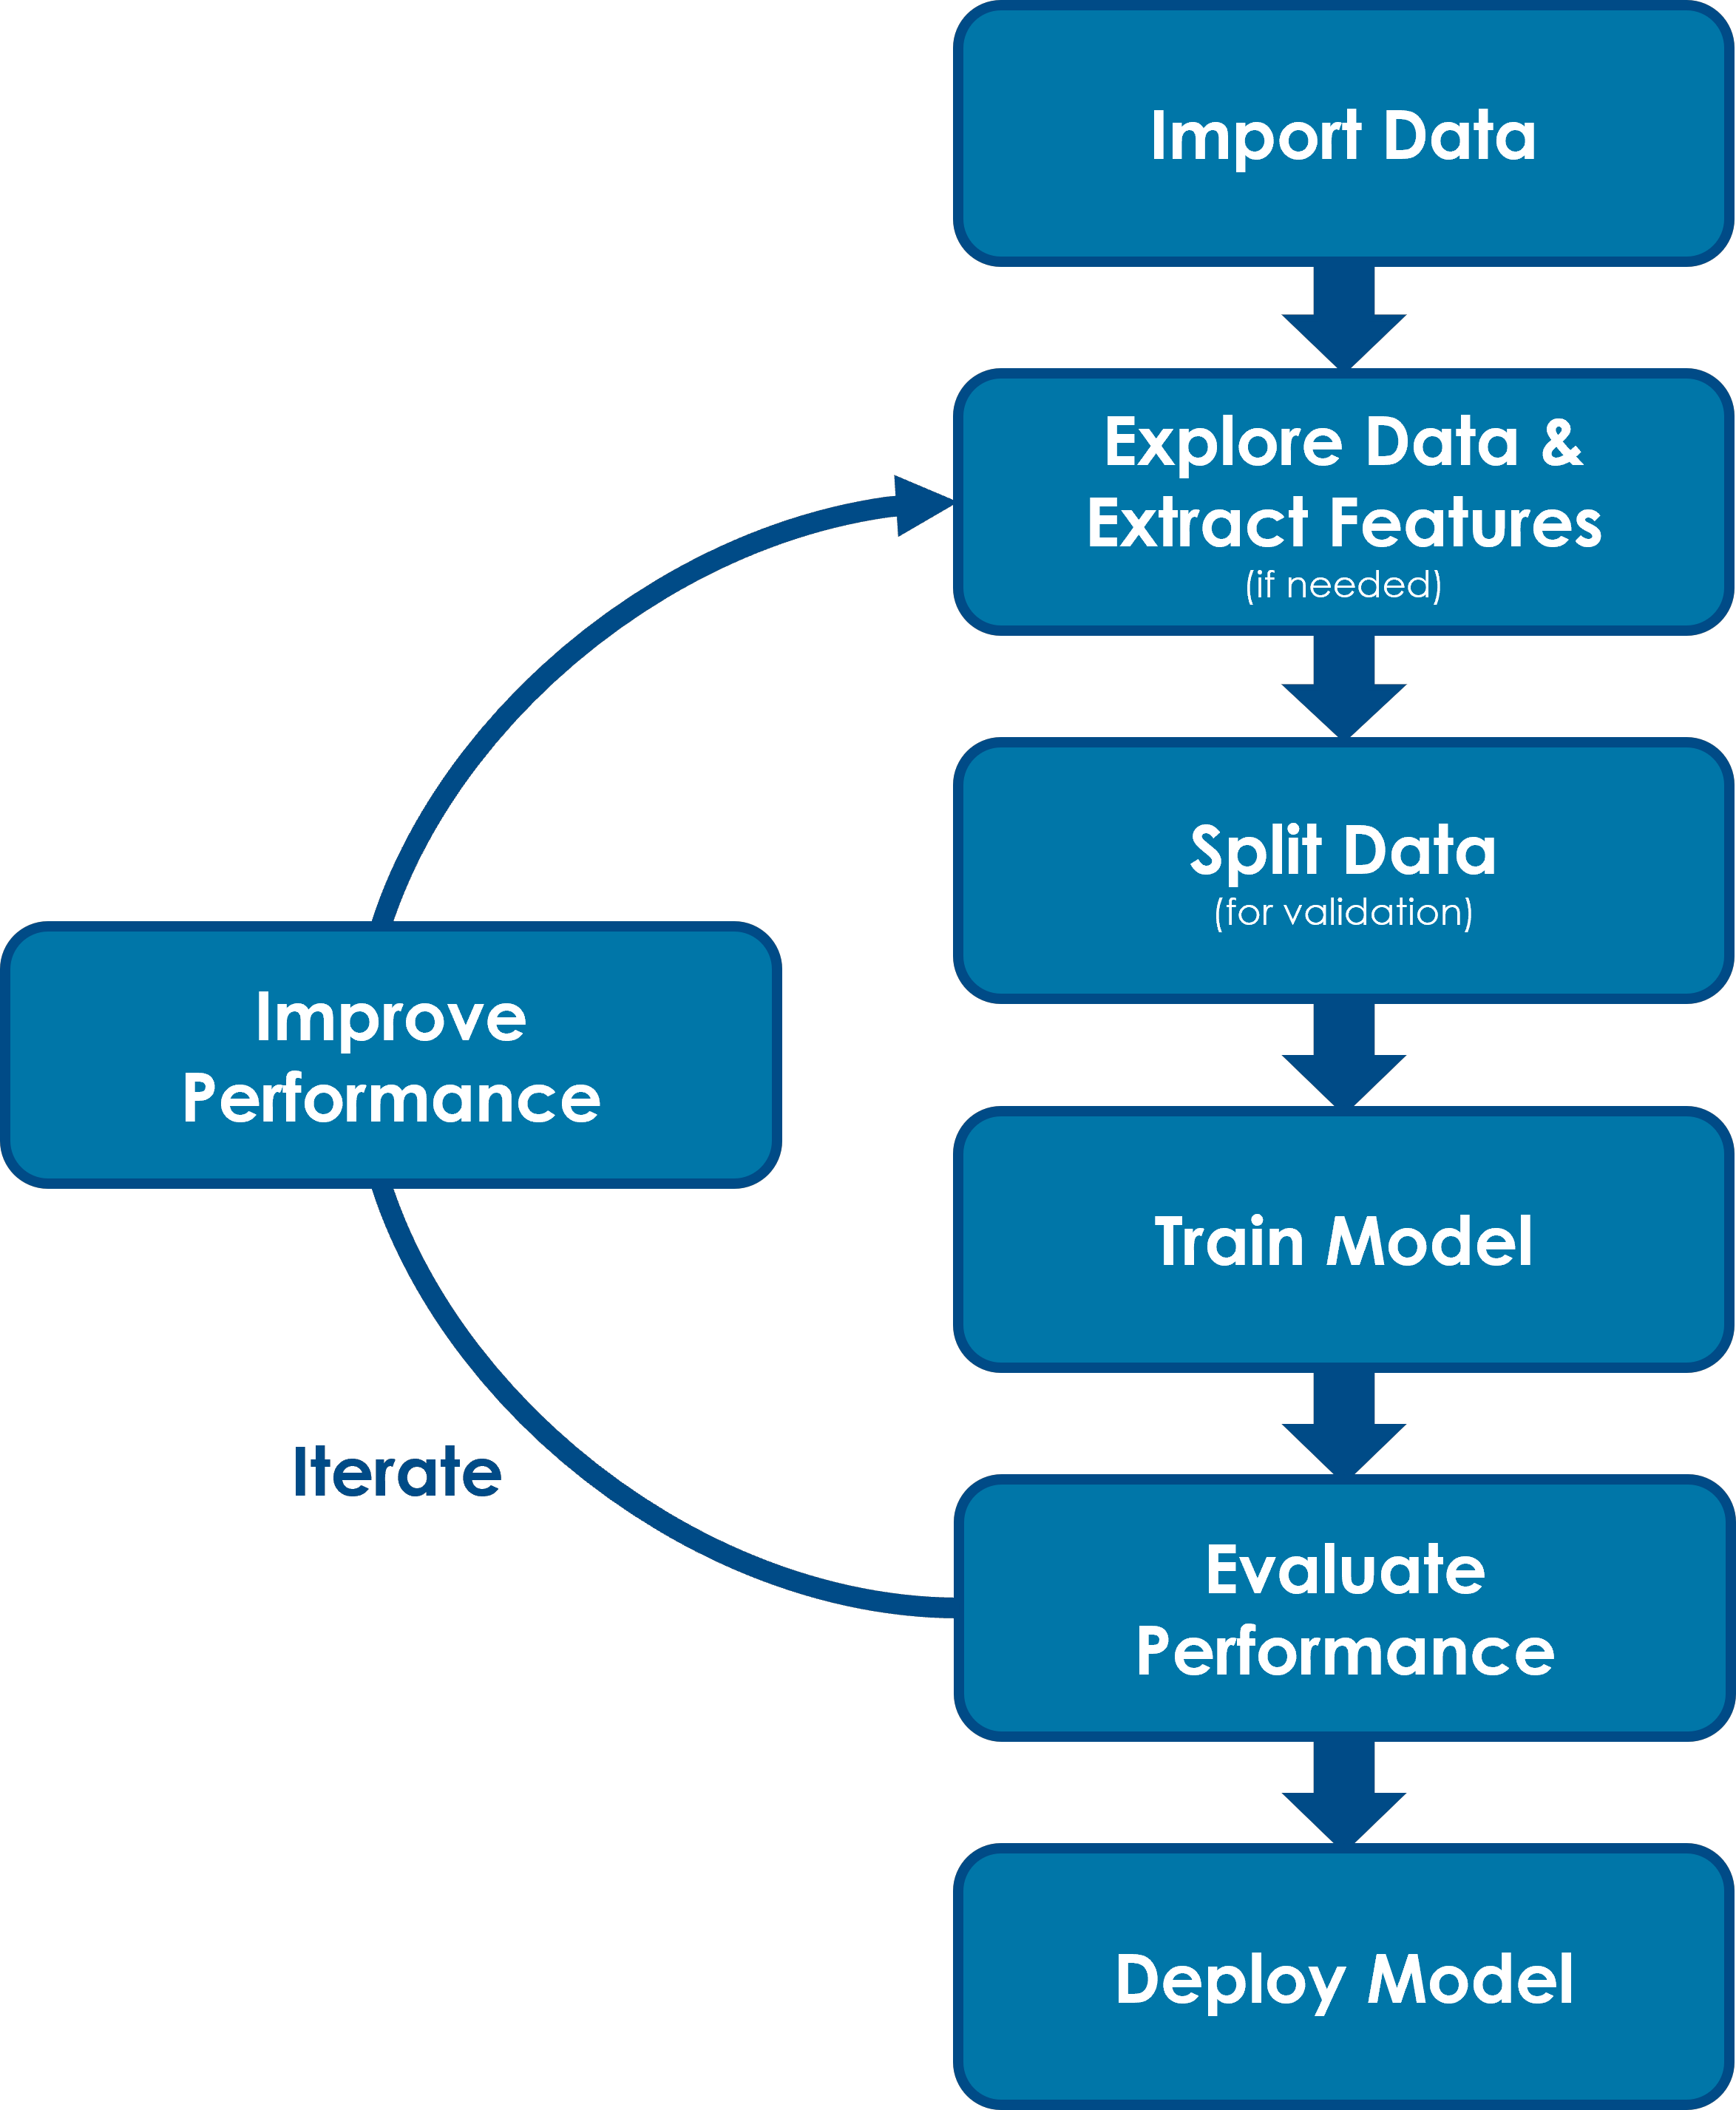

### How the Regression Model Actually Learns

- **Supervised learning.** You give the algorithm examples where the answer is already known - here, 36 months in which both the four features and the actual `Sales` are recorded. Learning means finding a function `f` such that `f(features)` comes as close as possible to the observed sales, and then applying that same `f` to a month whose answer you do not have.

- **What fitting means.** A linear model is just a weighted sum: `Sales = b0 + b1*feature1 + b2*feature2 + ...`. Fitting picks the five `b` values that make the total squared error across all training rows as small as possible. Nothing more mysterious than that - the app simply tries many model families and reports which one does it best.


### Turning History into Learning Examples

A regression has no sense of time; it sees only the columns you hand it. Each of the four features smuggles in a different piece of business knowledge:

- `MonthOfYear` carries calendar effects - Songkran, year-end, school terms.

- `LastMonth` carries momentum: whatever is happening now tends to continue.

- `SameMonthLastYear` carries seasonality, the annual shape you saw in the Step 0 plot.

- `MarketingSpend` carries the one driver management can actually control, which is what makes the model useful for planning rather than merely watching

### Train/Test Split

The first 3 years data is used to **train** the model. The latest year is held back as a** test** data

BUS_train = 
BUS_test = 

### Training the Model by Regression Learner App

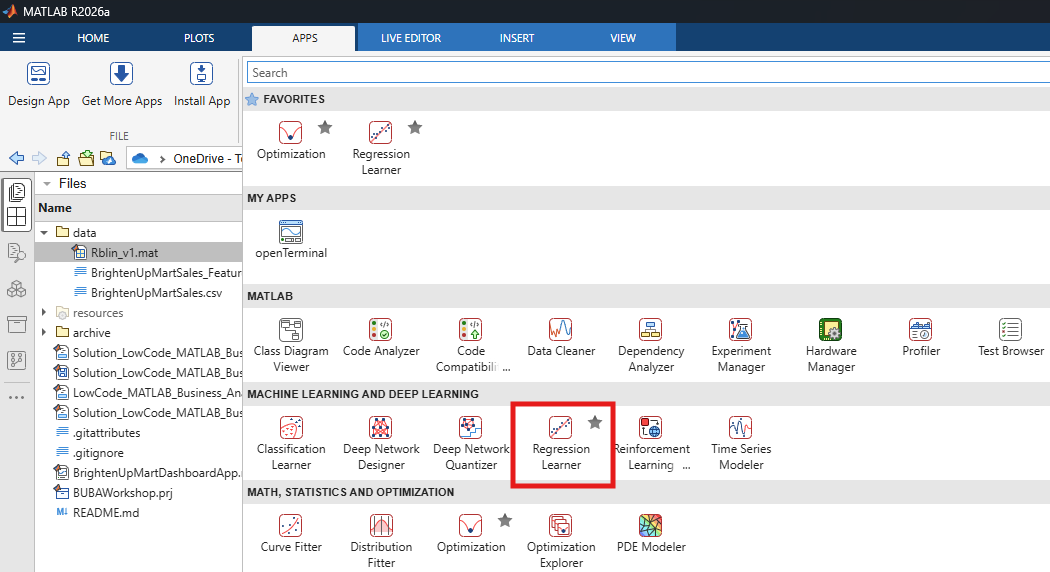

% or open it in by type "regressionLearner" in code

% regressionLearner

### Explain Model Predictions

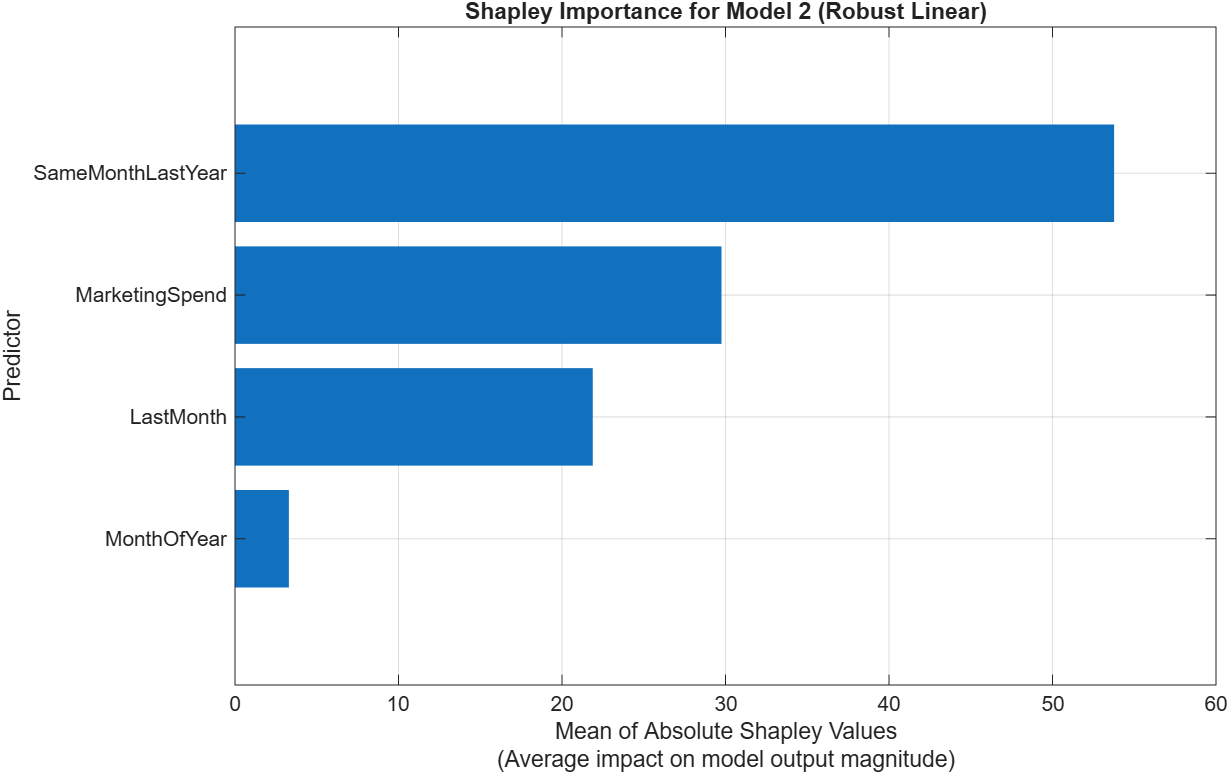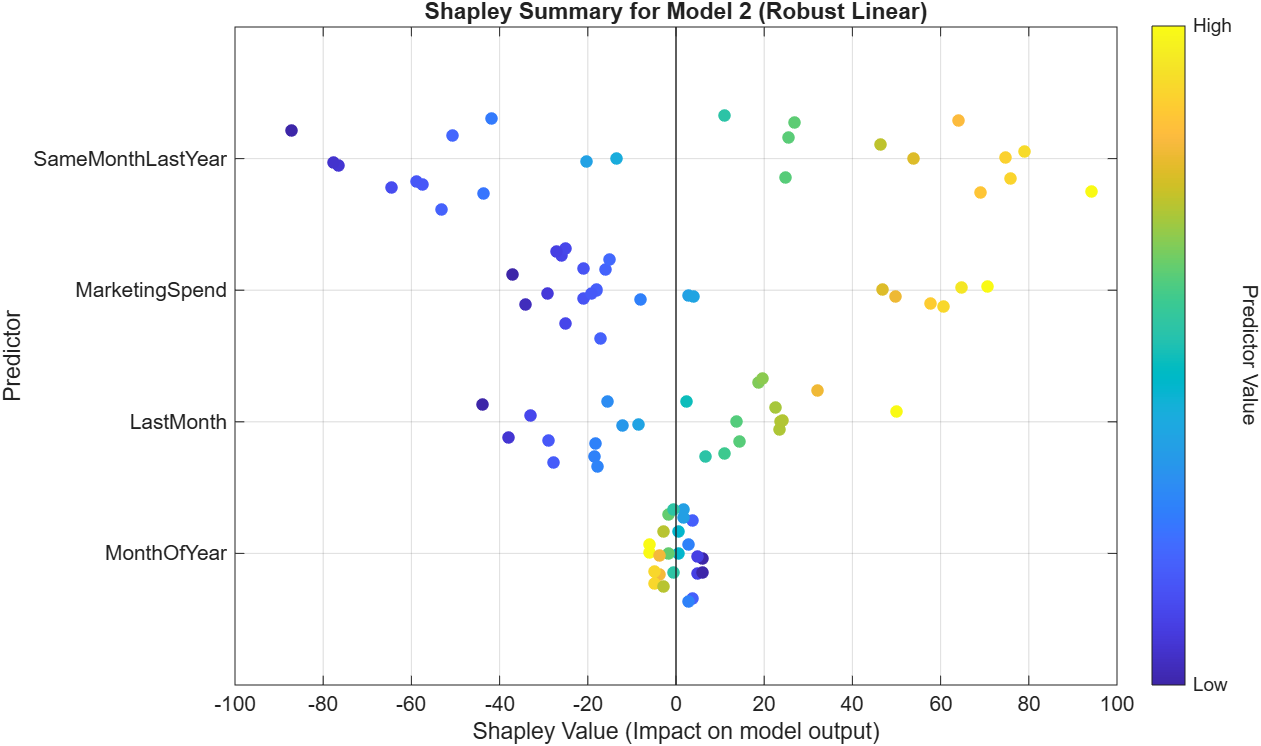

### Forecast the 3rd year sales

prepare the input table

input = 

prediction

forecast3rdYrSales = 

compare the result

m = BUS.Month(37:end); % date array for plotting


### Roll the model forward (recursive forecasting)

The model predicts **one** month. A multi-month forecast is therefore recursive: predict month h, then feed that prediction straight back in as the next month's `LastMonth`, while `SameMonthLastYear` is read from the history 12 months earlier.

As shown earlier, the input needed for forecasting are

- Month of Year ( i.e. 1 for Jan, 2 for Feb)

- Last Month Sales

- Same Month Last Year Sales

- Marketing Spend

Let's go step by step. Starting with forecast the upcoming month

#### Step-by-Step Forecasting

create needed input one by one

assign next month value

nextMonth = 

access last month sales

lastMonthSales = 

access same month last year sales

sameMonthLastYearSales = 

assign marketing spend

marketSpend = 

put all of them in a table

input = 

predict the next month sales

nextMonthSales = 

Now, do the same for next month (2), but the last month data is` nextMonthSales`

nextMonth = ;
sameMonthLastYearSales = ;
marketSpend = ;
lastMonthSales = ;
input = ;
nextMonthSales = RbLin.predictFcn(input)

Repeat the process until the desired duration is met. Easy? What if we want 50-years data?

#### Loop Function for Forecasting

targetm = 6; % forecast the next 6 months
focusmkt = 4; % boost marketing spend on April
[futureDates, plannedSpend, forecastSales] = createForecast(BUS, targetm, focusmkt, 'RbLin');
forecastTbl = table(futureDates, round(forecastSales), plannedSpend, 'VariableNames', {'Month','ForecastSales','PlannedMarketingSpend'})

### Plotting the Forecast

The forecast picks up right where history ends, and clearly shows the expected April demand spike from the planned promotion - exactly the kind of signal that feeds into Part 2.

## Part 2: Transportation Optimization

Forecasting tells us Brighten Up Mart needs to move about 947 units in April.

The next business question is purely operational: given three distribution centers with limited capacity and five stores that must each receive their share, which shipping routes should we use to meet every store's demand at the lowest possible total shipping cost?

This is the classic *transportation problem*, and it is a perfect example of business **optimization**: instead of trying options by hand in a spreadsheet, we let MATLAB search every feasible shipping plan and return the mathematically cheapest one..


### Setting Up the Distribution Network

The network scenario comes from `data\TransportOpt.xlsx`, one sheet each: **Shipping Cost** (THB per unit on each of the 3 by 5 centre-to-store routes), **Supply Share** (how capacity divides across the three distribution centres), and **Demand Share** (how demand divides across the five stores).

Each distribution center (DC) has a maximum monthly capacity, each store has a demand it must receive in full, and shipping a unit costs a different amount on every route depending on distance.

#### Import Shipping cost

convert table to array

shipCost = 

#### Import Supply Share

assign DC names and  DC share

dcNames = 
dcShare = 

#### Import Demand Share

assign store names and store share

storeNames = 
storeShare = 

**Total Demand and Supply** assign total demand from forecast data on the focus marketing month, then calculate total supply from total demand; a three percent buffer so the plan is not knife-edge

totalDemand = round(forecastTbl.ForecastSales(focusmkt))
totalSupply = ceil(totalDemand*1.03)

**Store demand:** `demand = round(totalDemand*storeShare)`. Rounding five shares rarely sums back to the total, so the remainder is pushed onto the last store. The store demands must sum exactly to `totalDemand`, or the equality constraint in the **Optimization** step cannot be satisfied.

demand = round(totalDemand*storeShare);
demand(end) = demand(end) + (totalDemand - sum(demand)); % make the summation of store demand equal to total demand
demand

**DC supply:** `totalSupply `split by `dcShare` with the remainder added to the first centre.

supply = round(totalSupply*dcShare);
supply(1) = supply(1) + (totalSupply - sum(supply));
supply

### Solving for the Least-Cost Shipping Plan by Optimize Live Task

The **Optimize** Live Task asks for the decision in business language, not for an algorithm. Four entries specify it completely:

- **Decision variable:** `shipUnit`, a 3 by 5 matrix holding how many units travel on each route, with a lower bound of 0 because you cannot ship negative stock.

- **Objective, minimise:** `sum(sum(shipCost.*shipUnit))`, the total shipping bill in THB.

- **Capacity constraint:** `sum(shipUnit,2) <= supply`. Summing each row across stores means no distribution centre ships more than it holds.

- **Service constraint:** `sum(shipUnit,1)' == demand`. Summing each column across centres means every store receives its full demand. Equality, not `<=`, because partial delivery is not an option her

string(month(forecastTbl.Month(focusmkt),'name'))
shipTbl = array2table(round(solution.shipUnit), 'VariableNames', storeNames, 'RowNames', dcNames)
totalCost = sum(sum(shipCost .* solution.shipUnit))

### How Much Did Optimization Save?

To show the value of optimization, we compare it against a common real-world habit: allocating stock first-come, first-served, store by store, without considering cost at all.

[alloc, naiveCost, savings] = naiveAllocation(supply, demand, shipCost, totalCost, forecastTbl, focusmkt);

Optimization saves BrightMart roughly 1M THB on this single month's shipment simply by choosing routes more intelligently, with no change to demand, supply, or prices.

## Part 3: AI Agentics for Data Analytics and Dashboard Intelligence

A forecast and an optimal shipping plan are only useful if the right people see them in time to act.

The plan is optimal **for the numbers you supplied**. Demand came from a forecast, so the honest follow-up question is how much the plan and the bill change if demand turns out five percent higher. That question is the reason the dashboard exists.

Don't know how to build a complex dashboard from MATLAB Live Script? MATLAB Agentic AI toolkit could give you some hands.

### Agentic AI

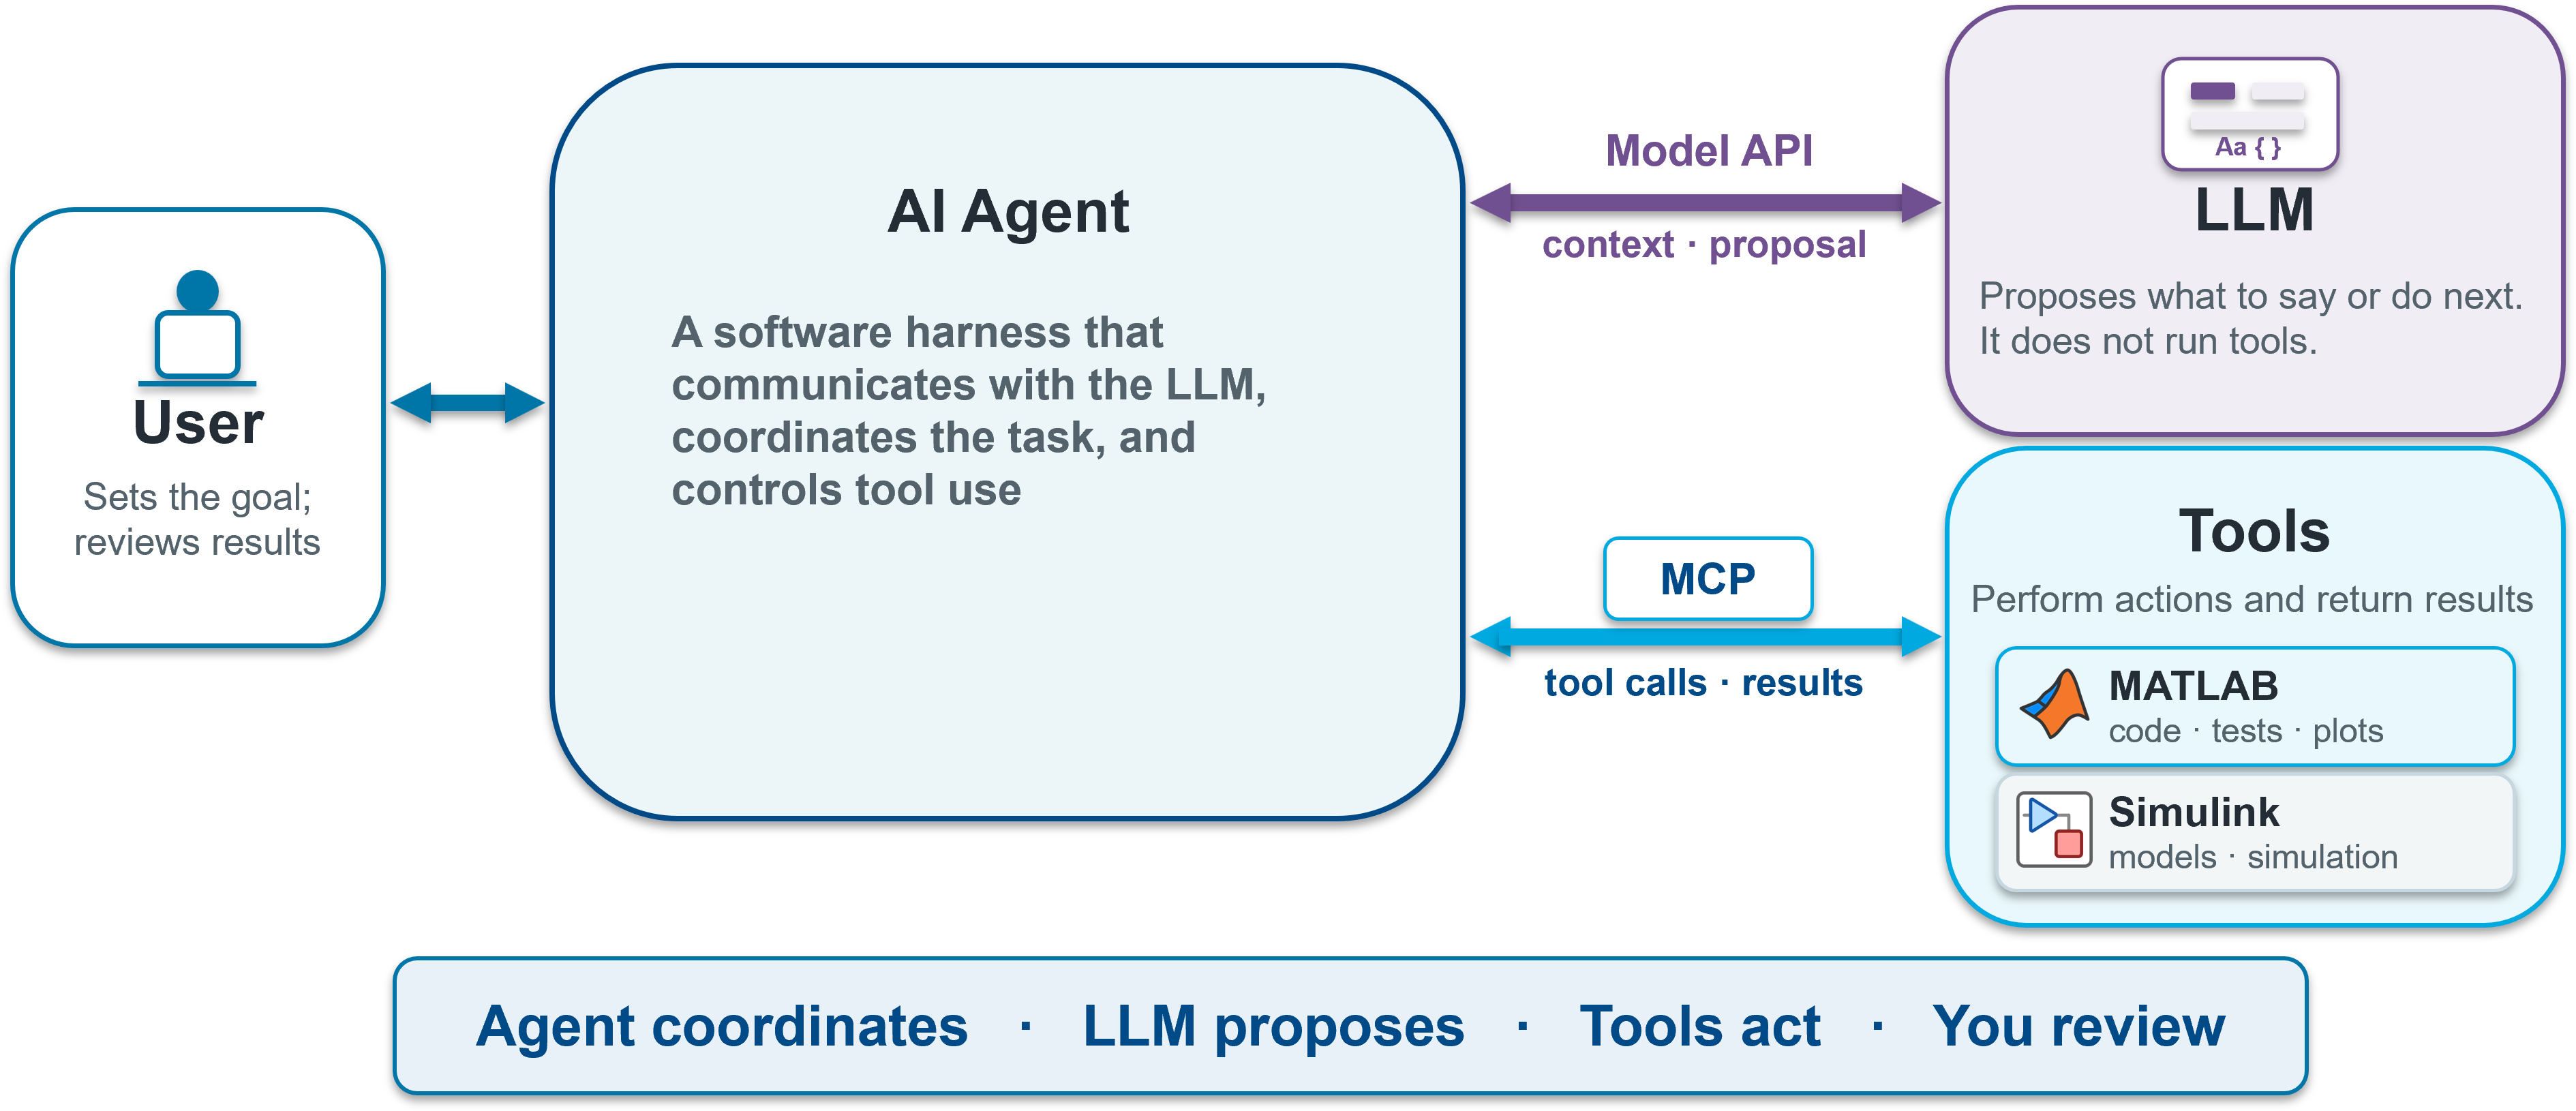

**What an AI agent adds, and what it does not.**

- A language model on its own predicts text. It does not compute, and it has no access to your data. Asking one for next April's sales gets you a fluent number with nothing behind it.

- An **agent** is a language model plus **tools** plus a loop. It reads the question, decides which tool to call - run the forecast, re-solve the shipping plan, look up a row - supplies the arguments, receives the result, and present it according to your prompt. Every number still comes from **MATLAB**. 

open BrightenUpMartAnalyticsApp.mlapp

## Appendix

If you would like to know how to make the features table from scratch

lag1 = [NaN; BUS.Sales(1:end-1)];
lag12 = [NaN(12,1); BUS.Sales(1:end-12)];
featTbl = table(month(BUS.Month), lag1, lag12, BUS.MarketingSpend, BUS.Sales, ...
    'VariableNames', {'MonthOfYear','LastMonth','SameMonthLastYear','MarketingSpend','Sales'});
featTbl = featTbl(13:end,:);
featTbl
clear lag1 lag12 featTbl 

createForecast function

function [futureDates, plannedSpend, forecastSales] = createForecast(BUS, targetm, focusmkt, model)
%CREATEFORECAST Create future dates, planned marketing spend, and forecasts

    % Resolve model input: struct or name in base workspace
    if ischar(model) || (isstring(model) && isscalar(model))
        modelName = char(model);
        model = evalin('base', modelName);
    end
    if ~isstruct(model) || ~isfield(model,'predictFcn')
        error('createForecast:InvalidModel', 'model must be a struct with a predictFcn field.');
    end

    monthIdx = 1:targetm;                             % create index from defined target m
    futureDates = BUS.Month(end) + calmonths(monthIdx)'; % create futureDates for forecasting
    
    rng(7);                                           % fix random seed
    plannedSpend = poissrnd(median(BUS.MarketingSpend(end-12:end)), [targetm,1]); % randomized planned marketing spend
    plannedSpend(focusmkt) = round(median(BUS.MarketingSpend(end-12:end)) + 2*std(BUS.MarketingSpend(end-12:end))); % assign spike marketing spend
    
    forecastSales = zeros(targetm,1);                 % allocate array for forecastSales
    lag1cur = BUS.Sales(end);                         % last month sales
    for h = monthIdx
        row = table(h, lag1cur, BUS.Sales(end-12+h), plannedSpend(h), ...
            'VariableNames', {'MonthOfYear','LastMonth','SameMonthLastYear','MarketingSpend'});
        forecastSales(h) = model.predictFcn(row);
        lag1cur = forecastSales(h);
    end

end

Naive cost calculation and plot

function [alloc, naiveCost, savings] = naiveAllocation(supply, demand, cost, totalCost, forecastTbl, focusmkt)
%NAIVEALLOCATION Compute a greedy (naive) allocation, cost, savings and plot
%   [alloc, naiveCost, savings] = naiveAllocation(supply, demand, cost, totalCost, forecastTbl, focusmkt)
%   supply : vector of supply by distribution center (nx1)
%   demand : vector of demand by store (1xm or mx1)
%   cost   : nxm cost matrix (same size as allocation)
%   totalCost : optimized total cost (scalar) for comparison
%   forecastTbl, focusmkt : used to label the plot

supply = supply(:);                 % ensure column
demand = demand(:)';                % ensure row
n = numel(supply);
m = numel(demand);
remaining = supply;
alloc = zeros(n,m);

for j = 1:m
    d = demand(j);
    for i = 1:n
        take = min(remaining(i), d);
        alloc(i,j) = take;
        remaining(i) = remaining(i) - take;
        d = d - take;
        if d <= 0
            break
        end
    end
end

naiveCost = sum(sum(cost .* alloc));
savings = naiveCost - totalCost;

% Plot comparison
figure;
bar(categorical({'Naive Allocation','MATLAB-Optimized'}), [naiveCost totalCost]);
ylabel('Total Shipping Cost (THB)');
title({
    sprintf('Optimization Impact: %s Distribution Plan', string(month(forecastTbl.Month(focusmkt),'name'))), ...
    sprintf('Savings: %0.0f THB', savings)
});

end